# Examine Well-Trained Session using Temporal Field Bayes - Time-in-Position Coding

fileDirs = [{'D:\WorkBigDataFiles\PFC\GE11_Session132'},...
    {'D:\WorkBigDataFiles\PFC\GE13_Session083'},...
    {'D:\WorkBigDataFiles\PFC\GE14_Session123'},...
    {'D:\WorkBigDataFiles\PFC\GE17_Session095'},...
    {'D:\WorkBigDataFiles\PFC\GE24_Session096'}];

binSize = 200;
dsRate = 50;
trlWindow = {[-800 2000]};
alignment = {'PokeIn'};
% trlWindow = {[-2000 800]};
% alignment = {'PokeOut'};
bayesType = 1; 
%bayseTypes: 1 = Poisson: use with raw spike counts; 2 = Bernoulli: use with binarized spike counts; 3 = Gaussian: Use with z-scored spike counts

numChancePerms = 10;

postCLim = [0 0.05];

cMap = load('roma.mat'); % flip
cMap = cMap.(cell2mat(fieldnames(cMap)));
cMap = flipud(cMap);
cMapNanW = cMap;
cMapNanW(1,:) = ones(1,3);


% trialWindowed = true;
trialWindowed = false;
 %#ok<*UNRCH> 

## Compile Data

tic;
for ani = 1:length(fileDirs)
    mlb = MLB_SM(fileDirs{ani});
    % Create Analysis Variables
    if ani == 1 
        % Behavior Variables
        fiscPokeOutLat = cell(length(fileDirs),1);
        fiscRwdDelivLat = cell(length(fileDirs),1);
        % Posteriors
        realPost = cell(mlb.seqLength, 1, length(fileDirs));
        chancePost_Pos = cell(mlb.seqLength, numChancePerms, length(fileDirs));
        chancePost_Time = cell(mlb.seqLength, numChancePerms, length(fileDirs));
        chancePost_Full = cell(mlb.seqLength, numChancePerms, length(fileDirs));
    end
    mlb.binSize = binSize;
    mlb.dsRate = dsRate;
    mlb.windows = trlWindow;
    mlb.alignments = alignment;
    mlb.bayesType = bayesType;
    
    fiscPokeOutLat{ani} = ([mlb.trialInfo(mlb.fiscTrials(~isnan(mlb.fiscTrials))).PokeOutIndex] - [mlb.trialInfo(mlb.fiscTrials(~isnan(mlb.fiscTrials))).PokeInIndex])'/1000;
    fiscRwdDelivLat{ani} = ([mlb.trialInfo(mlb.fiscTrials(~isnan(mlb.fiscTrials))).RewardIndex] - [mlb.trialInfo(mlb.fiscTrials(~isnan(mlb.fiscTrials))).PokeInIndex])'/1000;
    
    % Process Observations - FISC via Leave-1-Out
    mlb.SetLikes_FISC;
    mlb.Process_LikelyL1O;
    realPost(:,1,ani) = mlb.post;      
    %% Process Chance
    fprintf('.... processing chance... ');
    for perm = 1:numChancePerms 
        mlb.SetLikes_FISC;
        tempRealLikes = mlb.likeTrlSpikes;
        % Permute position ID to disrupt position specific coding
        chancePerm = permute(reshape(randperm(numel(mlb.fiscTrials)), size(mlb.fiscTrials)), [1,3,2]);
        tempPosPermLikes = tempRealLikes(chancePerm);
        mlb.likeTrlSpikes = tempPosPermLikes;
        mlb.Process_LikelyL1O;
        chancePost_Pos(:,perm,ani) = mlb.post;
        % Permute temporal organization to disrupt temporal coding 
        tempTimePermLikes = tempRealLikes;
        tempFullPermLikes = tempPosPermLikes;   % Use the position permuted data for the full permutation
        for t = 1:numel(tempRealLikes)
            chancePerm = randperm(size(mlb.likeTrlSpikes{t},1));
            tempTimePermLikes{t} = tempTimePermLikes{t}(chancePerm,:);
            tempFullPermLikes{t} = tempFullPermLikes{t}(chancePerm,:);
        end
        mlb.likeTrlSpikes = tempTimePermLikes;
        mlb.Process_LikelyL1O;
        chancePost_Time(:,perm,ani) = mlb.post;
        mlb.likeTrlSpikes = tempFullPermLikes;
        mlb.Process_LikelyL1O;
        chancePost_Full(:,perm,ani) = mlb.post;
    end
    fprintf('Complete\n');
end

Compiling StatMatrix Data....Completed


.... processing chance... 

Complete


Compiling StatMatrix Data....Completed


.... processing chance... 

Complete


Compiling StatMatrix Data....Completed


.... processing chance... 

Complete


Compiling StatMatrix Data....Completed


.... processing chance... 

Complete


Compiling StatMatrix Data....Completed


.... processing chance... 

Complete


toc
pokeOutLats = cell2mat(fiscPokeOutLat(:));
nearestPOtime = mlb.obsvTimeVect(find(mlb.obsvTimeVect<median(pokeOutLats),1,'last'));
rwdDelivLat = cell2mat(fiscRwdDelivLat(:));
nearestRWDtime = mlb.obsvTimeVect(find(mlb.obsvTimeVect<median(rwdDelivLat),1,'last'));
piNdx = find(mlb.likeTimeVect==0)+0.5;
poNdx = find(mlb.likeTimeVect==nearestPOtime)+0.5;
rwdNdx = find(mlb.likeTimeVect==nearestRWDtime)+0.5;
posNdx = find(diff(mlb.likeTimeVect)<0)+0.5;

## Collapse Trials Across Animals

tic;
%TIP = Time-In-Position
groupPostTIP_Real = cell(mlb.seqLength,1);
groupPostTime_Real = cell(mlb.seqLength,1);
groupPostPos_Real = cell(mlb.seqLength,1);

groupPostTIP_FullChance = cell(mlb.seqLength,2);
groupPostTime_FullChance = cell(mlb.seqLength,2);
groupPostPos_FullChance = cell(mlb.seqLength,2);

groupPostTIP_PosChance = cell(mlb.seqLength,2);
groupPostTime_PosChance = cell(mlb.seqLength,2);
groupPostPos_PosChance = cell(mlb.seqLength,2);

groupPostTIP_TimeChance = cell(mlb.seqLength,2);
groupPostTime_TimeChance = cell(mlb.seqLength,2);
groupPostPos_TimeChance = cell(mlb.seqLength,2);

for pos = 1:mlb.seqLength
    % Temporal Field PDF
    groupPostTIP_Real{pos} = cell2mat(realPost(pos,:,:));
    % Marginal Time PDF
    groupPostTime_Real{pos} = mlb.TabulateBayesPost(groupPostTIP_Real{pos}, mlb.decodeIDvects(:,1));
    % Marginal Position PDF
    groupPostPos_Real{pos} = mlb.TabulateBayesPost(groupPostTIP_Real{pos}, mlb.decodeIDvects(:,3));
    % Chance - Create temporary variables to reorganize & combine chance data
    % Full Chance
    tempPostTIP_FullChance = nan(length(mlb.obsvTimeVect), length(mlb.likeTimeVect), numChancePerms);
    tempPostTime_FullChance = nan(length(mlb.obsvTimeVect), length(mlb.obsvTimeVect), numChancePerms);
    tempPostPos_FullChance = nan(length(mlb.obsvTimeVect), mlb.seqLength, numChancePerms);
    % Position Chance
    tempPostTIP_PosChance = nan(length(mlb.obsvTimeVect), length(mlb.likeTimeVect), numChancePerms);
    tempPostTime_PosChance = nan(length(mlb.obsvTimeVect), length(mlb.obsvTimeVect), numChancePerms);
    tempPostPos_PosChance = nan(length(mlb.obsvTimeVect), mlb.seqLength, numChancePerms);
    % Time Chance
    tempPostTIP_TimeChance = nan(length(mlb.obsvTimeVect), length(mlb.likeTimeVect), numChancePerms);
    tempPostTime_TimeChance = nan(length(mlb.obsvTimeVect), length(mlb.obsvTimeVect), numChancePerms);
    tempPostPos_TimeChance = nan(length(mlb.obsvTimeVect), mlb.seqLength, numChancePerms);
    for perm = 1:numChancePerms
        % Full Chance
        curChanceFull = cell2mat(chancePost_Full(pos,perm,:));
        tempPostTIP_FullChance(:,:,perm) = mean(curChanceFull,3);
        tempPostTime_FullChance(:,:,perm) = mean(mlb.TabulateBayesPost(curChanceFull, mlb.decodeIDvects(:,1)),3);
        tempPostPos_FullChance(:,:,perm) = mean(mlb.TabulateBayesPost(curChanceFull, mlb.decodeIDvects(:,3)),3);
        % Position Chance
        curChancePos = cell2mat(chancePost_Pos(pos,perm,:));
        tempPostTIP_PosChance(:,:,perm) = mean(curChancePos,3);
        tempPostTime_PosChance(:,:,perm) = mean(mlb.TabulateBayesPost(curChancePos, mlb.decodeIDvects(:,1)),3);
        tempPostPos_PosChance(:,:,perm) = mean(mlb.TabulateBayesPost(curChancePos, mlb.decodeIDvects(:,3)),3);
        % Time Chance
        curChanceTime = cell2mat(chancePost_Time(pos,perm,:));
        tempPostTIP_TimeChance(:,:,perm) = mean(curChanceTime,3);
        tempPostTime_TimeChance(:,:,perm) = mean(mlb.TabulateBayesPost(curChanceTime, mlb.decodeIDvects(:,1)),3);
        tempPostPos_TimeChance(:,:,perm) = mean(mlb.TabulateBayesPost(curChanceTime, mlb.decodeIDvects(:,3)),3);
    end
    % Full Chance
    groupPostTIP_FullChance{pos,1} = mean(tempPostTIP_FullChance, 3,'omitnan');
    groupPostTime_FullChance{pos,1} = mean(tempPostTime_FullChance, 3, 'omitnan');
    groupPostPos_FullChance{pos,1} = mean(tempPostPos_FullChance, 3, 'omitnan');

    groupPostTIP_FullChance{pos,2} = std(tempPostTIP_FullChance, 0, 3,'omitnan');
    groupPostTime_FullChance{pos,2} = std(tempPostTime_FullChance, 0, 3, 'omitnan');
    groupPostPos_FullChance{pos,2} = std(tempPostPos_FullChance, 0, 3, 'omitnan');
    % Position Chance
    groupPostTIP_PosChance{pos,1} = mean(tempPostTIP_PosChance, 3,'omitnan');
    groupPostTime_PosChance{pos,1} = mean(tempPostTime_PosChance, 3, 'omitnan');
    groupPostPos_PosChance{pos,1} = mean(tempPostPos_PosChance, 3, 'omitnan');

    groupPostTIP_PosChance{pos,2} = std(tempPostTIP_PosChance, 0, 3,'omitnan');
    groupPostTime_PosChance{pos,2} = std(tempPostTime_PosChance, 0, 3, 'omitnan');
    groupPostPos_PosChance{pos,2} = std(tempPostPos_PosChance, 0, 3, 'omitnan');
    % Time Chance
    groupPostTIP_PosChance{pos,1} = mean(tempPostTIP_TimeChance, 3,'omitnan');
    groupPostTime_PosChance{pos,1} = mean(tempPostTime_TimeChance, 3, 'omitnan');
    groupPostPos_PosChance{pos,1} = mean(tempPostPos_TimeChance, 3, 'omitnan');

    groupPostTIP_PosChance{pos,2} = std(tempPostTIP_TimeChance, 0, 3,'omitnan');
    groupPostTime_PosChance{pos,2} = std(tempPostTime_TimeChance, 0, 3, 'omitnan');
    groupPostPos_PosChance{pos,2} = std(tempPostPos_TimeChance, 0, 3, 'omitnan');
end
numSeqs = size(groupPostTIP_Real{1},3);
toc

Elapsed time is 29.821904 seconds.


## Plot Temporal Field PDF

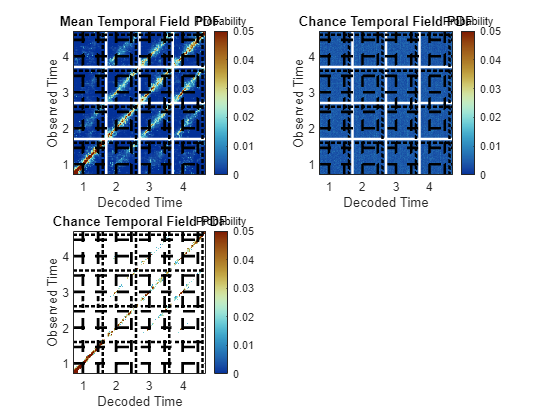

sps = nan(2);
figure; 
sps(1) = subplot(2,2,1);
tipALL_Real = cell2mat(groupPostTIP_Real);
tipALL_RealMean = mean(tipALL_Real,3,'omitnan');
imagesc(tipALL_RealMean, postCLim);
set(gca, 'ydir', 'normal', 'xtick', piNdx, 'xticklabels', 1:mlb.seqLength,...
    'ytick', piNdx, 'yticklabels', 1:mlb.seqLength);
colormap(sps(1), cMap);
cb = colorbar(gca, 'eastoutside');
set(get(cb,'Title'),'String','Probability');
title('Mean Temporal Field PDF')
xlabel('Decoded Time');
ylabel('Observed Time');
hold on;
for ndx = 1:length(piNdx)
    plot(get(gca, 'xlim'),repmat(piNdx(ndx), [1,2]), '--k','linewidth', 2);
    plot(get(gca, 'xlim'),repmat(poNdx(ndx), [1,2]), '--k','linewidth', 2);
    plot(get(gca, 'xlim'),repmat(rwdNdx(ndx), [1,2]), ':k','linewidth', 2);

    plot(repmat(piNdx(ndx), [1,2]), get(gca, 'ylim'), '--k','linewidth', 2);
    plot(repmat(poNdx(ndx), [1,2]), get(gca, 'ylim'), '--k','linewidth', 2);
    plot(repmat(rwdNdx(ndx), [1,2]), get(gca, 'ylim'), ':k','linewidth', 2);

    if ndx<length(piNdx)
        plot(repmat(posNdx(ndx), [1,2]), get(gca, 'ylim'), '-w','linewidth', 2);
        plot(get(gca, 'xlim'),repmat(posNdx(ndx), [1,2]), '-w','linewidth', 2);
    end
end
sps(2) = subplot(2,2,2);
tipALL_Chance = cell2mat(groupPostTIP_FullChance(:,1));
imagesc(tipALL_Chance, postCLim);
set(gca, 'ydir', 'normal', 'xtick', piNdx, 'xticklabels', 1:mlb.seqLength,...
    'ytick', piNdx, 'yticklabels', 1:mlb.seqLength);
colormap(sps(2), cMap);
cb = colorbar(gca, 'eastoutside');
set(get(cb,'Title'),'String','Probability');
title('Chance Temporal Field PDF')
xlabel('Decoded Time');
ylabel('Observed Time');
hold on;
for ndx = 1:length(piNdx)
    plot(get(gca, 'xlim'),repmat(piNdx(ndx), [1,2]), '--k','linewidth', 2);
    plot(get(gca, 'xlim'),repmat(poNdx(ndx), [1,2]), '--k','linewidth', 2);
    plot(get(gca, 'xlim'),repmat(rwdNdx(ndx), [1,2]), ':k','linewidth', 2);

    plot(repmat(piNdx(ndx), [1,2]), get(gca, 'ylim'), '--k','linewidth', 2);
    plot(repmat(poNdx(ndx), [1,2]), get(gca, 'ylim'), '--k','linewidth', 2);
    plot(repmat(rwdNdx(ndx), [1,2]), get(gca, 'ylim'), ':k','linewidth', 2);

    if ndx<length(piNdx)
        plot(repmat(posNdx(ndx), [1,2]), get(gca, 'ylim'), '-w','linewidth', 2);
        plot(get(gca, 'xlim'),repmat(posNdx(ndx), [1,2]), '-w','linewidth', 2);
    end
end
tipSigVals = nan(size(tipALL_Chance));
for t1 = 1:size(tipALL_Real,1)
    for t2 = 1:size(tipALL_Real,2)
        [~,tipSigVals(t1,t2)] = ttest(squeeze(tipALL_Real(t1,t2,:)), tipALL_Chance(t1,t2), 'Tail', 'Right');
    end
end
[~,q] = mafdr(tipSigVals(:));
sigLog = reshape(q,size(tipSigVals))<0.05;
tipALL_RealMean(~sigLog) = nan;
sps(3) = subplot(2,2,3);
imagesc(tipALL_RealMean, postCLim);
colormap(sps(3),cMapNanW);
set(gca, 'ydir', 'normal', 'xtick', piNdx, 'xticklabels', 1:mlb.seqLength,...
    'ytick', piNdx, 'yticklabels', 1:mlb.seqLength);
cb = colorbar(gca, 'eastoutside');
set(get(cb,'Title'),'String','Probability');
title('Chance Thresholded Temporal Field PDF (FDR)')
xlabel('Decoded Time');
ylabel('Observed Time');
hold on;
for ndx = 1:length(piNdx)
    plot(get(gca, 'xlim'),repmat(piNdx(ndx), [1,2]), '--k','linewidth', 2);
    plot(get(gca, 'xlim'),repmat(poNdx(ndx), [1,2]), '--k','linewidth', 2);
    plot(get(gca, 'xlim'),repmat(rwdNdx(ndx), [1,2]), ':k','linewidth', 2);

    plot(repmat(piNdx(ndx), [1,2]), get(gca, 'ylim'), '--k','linewidth', 2);
    plot(repmat(poNdx(ndx), [1,2]), get(gca, 'ylim'), '--k','linewidth', 2);
    plot(repmat(rwdNdx(ndx), [1,2]), get(gca, 'ylim'), ':k','linewidth', 2);

    if ndx<length(piNdx)
        plot(repmat(posNdx(ndx), [1,2]), get(gca, 'ylim'), '-w','linewidth', 2);
        plot(get(gca, 'xlim'),repmat(posNdx(ndx), [1,2]), '-w','linewidth', 2);
    end
end

## Collapse Temporal Lag

tic;
transMatPosts = cell(mlb.seqLength);
transMatPost_TimeLagDiag = cell(mlb.seqLength);
transMatPost_TimeLagCDF = cell(mlb.seqLength);
transMatPost_MeanDiag = nan(mlb.seqLength,mlb.seqLength,numSeqs);

transMatChance = cell(mlb.seqLength);
transMatChance_TimeLagDiag = cell(mlb.seqLength);
transMatChance_TimeLagCDF = cell(mlb.seqLength);
transMatChance_MeanDiag = nan(mlb.seqLength, mlb.seqLength);
for p1 = 1:mlb.seqLength
    for p2 = 1:mlb.seqLength
        tempTIP_Post = groupPostTIP_Real{p1}(:,mlb.decodeIDvects(:,3)==p2,:);
        if trialWindowed 
            tempTrlMask = false(size(tempTIP_Post));
            tempTrlMask(mlb.obsvTimeVect>=0 & mlb.obsvTimeVect<=nearestPOtime, mlb.obsvTimeVect>=0 & mlb.obsvTimeVect<=nearestPOtime,:) = true;
            transMatPosts{p1,p2} = reshape(tempTIP_Post(tempTrlMask), [max(max(sum(tempTrlMask))),max(max(sum(tempTrlMask))),numSeqs]);
        else
            transMatPosts{p1,p2} = tempTIP_Post;
        end
        [transMatPost_TimeLagDiag{p1,p2}, tempLagVect, ~] = mlb.DiagonalLagMeanCollapse(transMatPosts{p1,p2});
        transMatPost_TimeLagCDF{p1,p2} = histcounts(mean(transMatPost_TimeLagDiag{p1,p2},1), size(transMatPost_TimeLagDiag{p1,p2},2), 'Normalization', 'cdf');
        transMatPost_MeanDiag(p1,p2,:) = transMatPost_TimeLagDiag{p1,p2}(:,tempLagVect==0); % ONLY the diagonal 
%         transMatPost_MeanDiag(p1,p2,:) = mean(transMatPost_TimeLagDiag{p1,p2}(:), 'omitnan'); % WHOLE quadrant

        tempTIP_Chance = groupPostTIP_FullChance{p1,1}(:,mlb.decodeIDvects(:,3)==p2);
        if trialWindowed
            transMatChance{p1,p2} = reshape(tempTIP_Chance(tempTrlMask(:,:,1)), [max(sum(tempTrlMask(:,:,1),1)), max(sum(tempTrlMask(:,:,1),1))]);
        else
            transMatChance{p1,p2} = tempTIP_Chance;
        end
        [transMatChance_TimeLagDiag{p1,p2}, tempLagVect, lagCounts] = mlb.DiagonalLagMeanCollapse(transMatChance{p1,p2});
        transMatChance_TimeLagCDF{p1,p2} = histcounts(transMatChance_TimeLagDiag{p1,p2}, size(transMatChance_TimeLagDiag{p1,p2},2), 'Normalization', 'cdf');
        transMatChance_MeanDiag(p1,p2) = transMatChance_TimeLagDiag{p1,p2}(:,tempLagVect==0); % ONLY the diagonal 
%         transMatChance_MeanDiag(p1,p2) = mean(transMatChance_TimeLagDiag{p1,p2}(:), 'omitnan'); % WHOLE quadrant
    end
end
toc

Elapsed time is 1.946323 seconds.


## Plot Temporal Lag Across Position

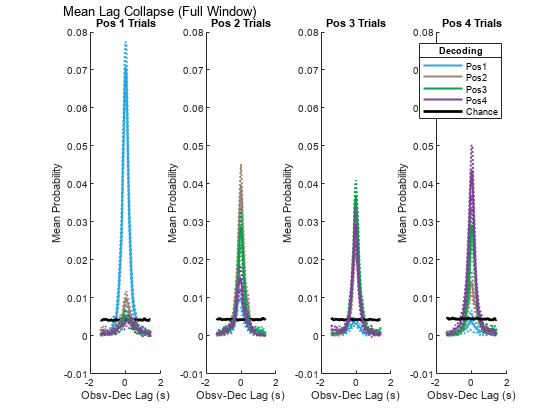

figure; 
sp = nan(1,mlb.seqLength);
plt = nan(1,mlb.seqLength+1);
for posObs = 1:mlb.seqLength
    sp(posObs) = subplot(1, mlb.seqLength, posObs);
    for posDec = 1:mlb.seqLength
        if trialWindowed
            plt(posDec) = mlb.PlotMeanVarLine(tempLagVect(lagCounts>=max(lagCounts/4))*mode(diff(mlb.obsvTimeVect)), transMatPost_TimeLagDiag{posObs, posDec}(:,lagCounts>=max(lagCounts/4)), 1, 0.05, mlb.PositionColors(posDec,:));
        else
            plt(posDec) = mlb.PlotMeanVarLine(tempLagVect(lagCounts>=max(lagCounts/2))*mode(diff(mlb.obsvTimeVect)), transMatPost_TimeLagDiag{posObs, posDec}(:,lagCounts>=max(lagCounts/2)), 1, 0.05, mlb.PositionColors(posDec,:));
        end
        if posObs==posDec
            if trialWindowed
                plt(mlb.seqLength+1) = plot(tempLagVect(lagCounts>=max(lagCounts/4))*mode(diff(mlb.obsvTimeVect)), transMatChance_TimeLagDiag{posObs,posDec}(lagCounts>=max(lagCounts/4)), '-k', 'linewidth', 2);
            else
                plt(mlb.seqLength+1) = plot(tempLagVect(lagCounts>=max(lagCounts/2))*mode(diff(mlb.obsvTimeVect)), transMatChance_TimeLagDiag{posObs,posDec}(lagCounts>=max(lagCounts/2)), '-k', 'linewidth', 2);
            end
        end
    end
    title(sprintf('Pos %i Trials',posObs));
    xlabel('Obsv-Dec Lag (s)');
    ylabel('Mean Probability');
end
linkaxes(sp, 'y')
if trialWindowed
    annotation(gcf,'textbox', [0.1 0.95 0.9 0.05],...
        'String', 'Mean Lag Collapse (Trial Period Only)',...
        'FontSize',10, 'edgecolor', 'none', 'horizontalalignment', 'left');
else
    annotation(gcf,'textbox', [0.1 0.95 0.9 0.05],...
        'String', 'Mean Lag Collapse (Full Window)',...
        'FontSize',10, 'edgecolor', 'none', 'horizontalalignment', 'left');
end
leg = legend(plt, [cellfun(@(a){sprintf('Pos%i',a)}, num2cell(1:4,[1,4])), {'Chance'}]);
set(get(leg, 'Title'), 'String', 'Decoding')

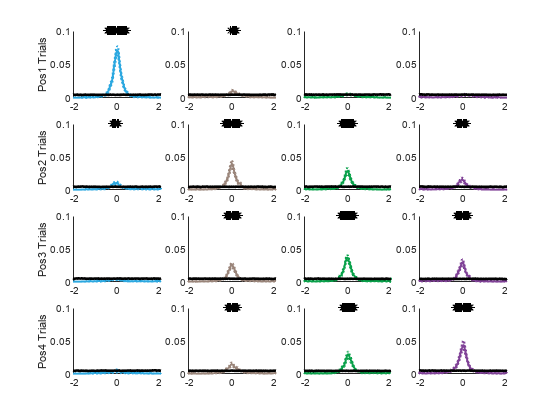

figure;
sp = nan(mlb.seqLength);
for posObs = 1:mlb.seqLength
    for posDec = 1:mlb.seqLength
        tempObsv = transMatPost_TimeLagDiag{posObs,posDec}(:,lagCounts>=max(lagCounts/4));
        tempChance = transMatChance_TimeLagDiag{posObs,posDec}(lagCounts>=max(lagCounts/4));
        sp(posObs,posDec) = subplot(mlb.seqLength, mlb.seqLength, sub2ind([mlb.seqLength, mlb.seqLength], posDec, posObs));
        tempSigVect = false(1,size(tempObsv,2));
        for t = 1:size(tempObsv,2)
            tempSigVect(t) = ttest(tempObsv(:,t), tempChance(t), 'Alpha', 0.05/size(tempObsv,2), 'Tail', 'Right');
%             tempSigVect(t) = ttest(tempObsv(:,t), tempChance(t), 'Alpha', 0.05, 'Tail', 'Right');
        end
        mlb.PlotMeanVarLine(tempLagVect(lagCounts>=max(lagCounts/4))*mode(diff(mlb.obsvTimeVect)), tempObsv, 1, 0.05, mlb.PositionColors(posDec,:));
        tempSigVect = tempSigVect.*0.1;
        tempSigVect(tempSigVect==0) = nan;
        scatter(tempLagVect(lagCounts>=max(lagCounts/4))*mode(diff(mlb.obsvTimeVect)), tempSigVect,'*', 'k');
        hold on;
        plot(tempLagVect(lagCounts>=max(lagCounts/4))*mode(diff(mlb.obsvTimeVect)), tempChance, 'k', 'linewidth', 2)
    end
end
linkaxes(sp, 'xy');
for pos = 1:mlb.seqLength
    ylabel(sp(pos,1), sprintf('Pos%i Trials', pos));
end

## TransMat Mean Diagonal Decoding vs Chance

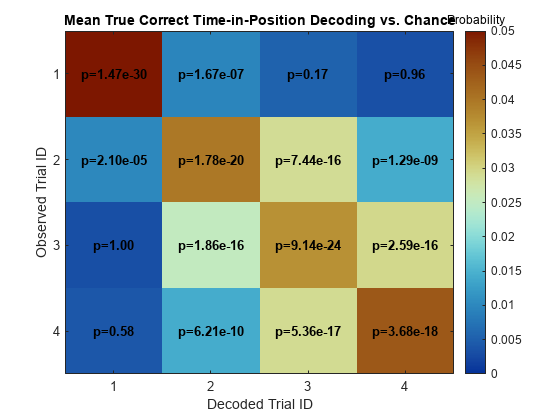

figure;
imagesc(mean(transMatPost_MeanDiag,3,'omitnan'), postCLim);
colormap(cMap)
cb = colorbar(gca, 'eastoutside');
set(get(cb,'Title'),'String','Probability');
title('Mean True Correct Time-in-Position Decoding vs. Chance')
set(gca, 'xtick', 1:mlb.seqLength, 'ytick', 1:mlb.seqLength)
xlabel('Decoded Trial ID');
ylabel('Observed Trial ID');
for oPos = 1:mlb.seqLength
    for dPos = 1:mlb.seqLength
        [h,p] = ttest(squeeze(transMatPost_MeanDiag(oPos,dPos,:)), transMatChance_MeanDiag(oPos,dPos), 'Alpha', 0.05/4, 'Tail', 'Right');
        if p<0.05
            text(dPos,oPos, sprintf('p=%.02i',p), 'FontSize', 10, 'FontWeight', 'Bold', 'HorizontalAlignment','center');
        else
            text(dPos,oPos, sprintf('p=%.02f',p), 'FontSize', 10, 'FontWeight', 'Bold', 'HorizontalAlignment','center');
        end
    end
end

## TransMat Mean Diagonal Decoding ANOVAs

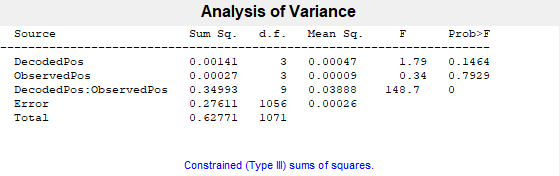

p =     0.1464
    0.7929
    0.0000


tbl = 6×7 cell array
    {'Source'                }    {'Sum Sq.'   }    {'d.f.'}    {'Singular?'}    {'Mean Sq.'  }    {'F'       }    {'Prob>F'     }
    {'DecodedPos'            }    {[    0.0014]}    {[   3]}    {[        0]}    {[4.6932e-04]}    {[  1.7950]}    {[     0.1464]}
    {'ObservedPos'           }    {[2.7049e-04]}    {[   3]}    {[        0]}    {[9.0163e-05]}    {[  0.3448]}    {[     0.7929]}
    {'DecodedPos:ObservedPos'}    {[    0.3499]}    {[   9]}    {[        0]}    {[    0.0389]}    {[148.7036]}    {[7.4697e-181]}
    {'Error'                 }    {[    0.2761]}    {[1056]}    {[        0]}    {[2.6146e-04]}    {0×0 double}    {0×0 double   }
    {'Total'                 }    {[    0.6277]}    {[1071]}    {[        0]}    {0×0 double  }    {0×0 double}    {0×0 double   }


stats = struct with fields:
         source: 'anovan'
          resid: [1072×1 double]
         coeffs: [25×1 double]
            Rtr: [16×16 double]
       rowbasis: [16×25 double]
            dfe: 1056
            mse: 2.6146e-04
    nullproject: [25×16 double]
          terms: [3×2 double]
        nlevels: [2×1 double]
     continuous: [0 0]
         vmeans: [2×1 double]
       termcols: [4×1 double]
     coeffnames: {25×1 cell}
           vars: [25×2 double]
       varnames: {2×1 cell}
       grpnames: {2×1 cell}
        vnested: []
            ems: [4×4 double]
          denom: []
        dfdenom: []
        msdenom: []
         varest: []
          varci: []
       txtdenom: []
         txtems: []
        rtnames: []


terms =      1     0
     0     1
     1     1


obsvPosID = repmat((1:mlb.seqLength)',[1, mlb.seqLength, numSeqs]);
decodePosID = repmat(1:mlb.seqLength,[mlb.seqLength,1, numSeqs]);
tempLagMtx = nan(mlb.seqLength);
for lag = 1:length(mlb.lagVect)
    tempLagMtx(triu(true(mlb.seqLength),mlb.lagVect(lag)) & tril(true(mlb.seqLength),mlb.lagVect(lag))) = mlb.lagVect(lag);
end
odLagID = repmat(tempLagMtx, [1,1,numSeqs]);
% [p,tbl,stats,terms] = anovan(transMatPost_MeanDiag(:),{decodePosID(:), obsvPosID(:), odLagID(:)}, 'model', 'full', 'varnames',{'DecodedPos', 'ObservedPos', 'Lag'}, 'SSType', 1)
[p,tbl,stats,terms] = anovan(transMatPost_MeanDiag(:),{decodePosID(:), obsvPosID(:)}, 'model', 'full', 'varnames',{'DecodedPos', 'ObservedPos'}, 'SSType', 3)

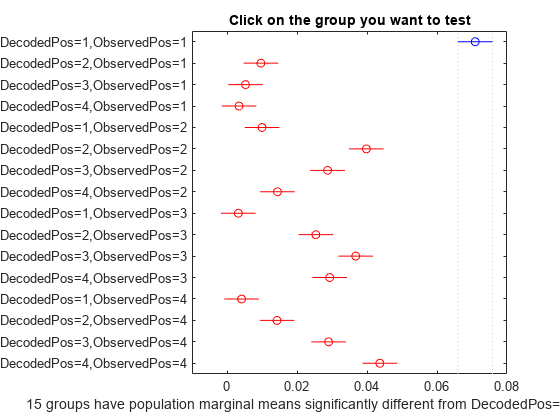

ans =     1.0000    2.0000    0.0513    0.0612    0.0711    0.0000
    1.0000    3.0000    0.0557    0.0656    0.0755    0.0000
    1.0000    4.0000    0.0576    0.0675    0.0774    0.0000
    1.0000    5.0000    0.0510    0.0609    0.0708    0.0000
    1.0000    6.0000    0.0212    0.0311    0.0410    0.0000
    1.0000    7.0000    0.0323    0.0422    0.0521    0.0000
    1.0000    8.0000    0.0466    0.0565    0.0664    0.0000
    1.0000    9.0000    0.0578    0.0677    0.0776    0.0000
    1.0000   10.0000    0.0357    0.0456    0.0554    0.0000
    1.0000   11.0000    0.0243    0.0342    0.0440    0.0000


figure; 
multcompare(stats, 'Dimension', [2 1], 'CriticalValueType','bonferroni')

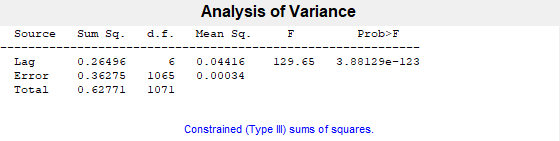

p = 3.8813e-123

tbl = 4×7 cell array
    {'Source'}    {'Sum Sq.'}    {'d.f.'}    {'Singular?'}    {'Mean Sq.'  }    {'F'       }    {'Prob>F'     }
    {'Lag'   }    {[ 0.2650]}    {[   6]}    {[        0]}    {[    0.0442]}    {[129.6528]}    {[3.8813e-123]}
    {'Error' }    {[ 0.3627]}    {[1065]}    {[        0]}    {[3.4061e-04]}    {0×0 double}    {0×0 double   }
    {'Total' }    {[ 0.6277]}    {[1071]}    {[        0]}    {0×0 double  }    {0×0 double}    {0×0 double   }


stats = struct with fields:
         source: 'anovan'
          resid: [1072×1 double]
         coeffs: [8×1 double]
            Rtr: [7×7 double]
       rowbasis: [7×8 double]
            dfe: 1065
            mse: 3.4061e-04
    nullproject: [8×7 double]
          terms: 1
        nlevels: 7
     continuous: 0
         vmeans: 0
       termcols: [2×1 double]
     coeffnames: {8×1 cell}
           vars: [8×1 double]
       varnames: {'Lag'}
       grpnames: {{7×1 cell}}
        vnested: []
            ems: [2×2 double]
          denom: []
        dfdenom: []
        msdenom: []
         varest: []
          varci: []
       txtdenom: []
         txtems: []
        rtnames: []


terms = 1


[p,tbl,stats,terms] = anovan(transMatPost_MeanDiag(:),{odLagID(:)}, 'varnames', 'Lag', 'SSType', 3)

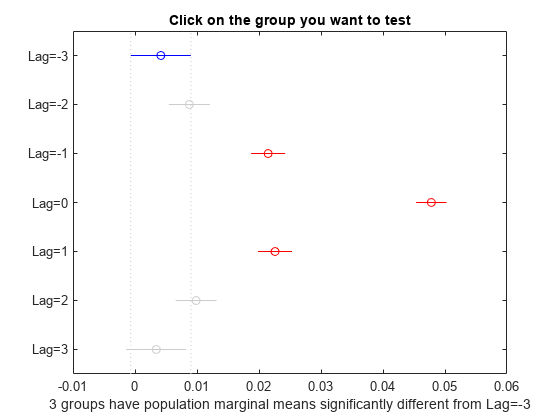

ans =     1.0000    2.0000   -0.0127   -0.0046    0.0035    0.6389
    1.0000    3.0000   -0.0250   -0.0173   -0.0096    0.0000
    1.0000    4.0000   -0.0511   -0.0436   -0.0362         0
    1.0000    5.0000   -0.0261   -0.0184   -0.0107    0.0000
    1.0000    6.0000   -0.0138   -0.0057    0.0024    0.3758
    1.0000    7.0000   -0.0087    0.0007    0.0101    1.0000
    2.0000    3.0000   -0.0188   -0.0127   -0.0066    0.0000
    2.0000    4.0000   -0.0448   -0.0390   -0.0333         0
    2.0000    5.0000   -0.0199   -0.0138   -0.0077    0.0000
    2.0000    6.0000   -0.0077   -0.0011    0.0056    0.9990


multcompare(stats)